# Optimización por Colonia de Hormigas (ACO) para el Problema del Agente Viajero (TSP)

**Profesor:** PhD. Marlon Moscoso Martínez

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ALGORITMO DE OPTIMIZACIÓN POR COLONIA DE HORMIGAS (ACO) PARA TSP
% Basado y mejorado a partir del script de caminos Hamiltonianos visto en
% clases.
%
% Se construye la matriz de distancias usando las aristas definidas.
% Luego se aplica ACO con parámetros configurables para buscar la ruta 
% hamiltoniana (ciclo) de menor longitud.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clc; clear; close all;

disp('===== ALGORITMO DE OPTIMIZACIÓN POR COLONIA DE HORMIGAS (ACO) PARA TSP =====');

===== ALGORITMO DE OPTIMIZACIÓN POR COLONIA DE HORMIGAS (ACO) PARA TSP =====



%% PARÁMETROS DEL PROBLEMA
% nodos1 y nodos2 indican las conexiones (aristas), y peso su coste/distancia.
nodos1 = [1 1 1 2 2 6 6 3 3 5 7];
nodos2 = [2 3 6 7 3 3 5 7 5 4 4];
peso =   [5 3.1 5.2 5.2 4.9 3.2 4.7 3 6 5.5 4.8];

% Cantidad total de nodos en el problema
numNodos = max( [nodos1,nodos2] );

% Construimos una matriz de distancias (numNodos x numNodos).
% Inicialmente con Inf para indicar que no hay conexión directa.
distMatrix = inf(numNodos);
for i=1:numNodos
    distMatrix(i,i) = 0;  % distancia cero al nodo mismo
end

% Llenamos la matriz de distancias a partir de (nodos1, nodos2, peso).
for i = 1:length(nodos1)
    distMatrix(nodos1(i), nodos2(i)) = peso(i);
    distMatrix(nodos2(i), nodos1(i)) = peso(i);  % Si tu grafo es no dirigido (TSP usual)
end

%% PARÁMETROS DE LA COLONIA DE HORMIGAS
numHormigas    = 5;     % Número de hormigas
maxIteraciones = 10;    % Número máximo de iteraciones
% alpha          = 1;     % Importancia de las feromonas
% beta           = 5;     % Importancia de la heurística (1/distancia)
alpha          = 0.5;   % Importancia de las feromonas
beta           = 0.5;   % Importancia de la heurística (1/distancia)
rho            = 0.5;   % Tasa de evaporación de las feromonas
Q              = 1;     % Constante de depósito de feromonas (para global update)

% Semilla aleatoria para reproducibilidad (opcional)
rng('default');

%% INICIALIZACIÓN DE FEROMONAS
% Tau(i,j) es la feromona en la arista (i,j).
% Inicialmente, un valor pequeño constante en todas las aristas (p.ej. 1/(numNodos^2))
tau = ones(numNodos, numNodos) * (1 / (numNodos^2));

% Matriz heurística (eta), donde eta(i,j) = 1/distMatrix(i,j) si hay conexión
eta = 1 ./ distMatrix;
eta(isinf(eta)) = 0;  % Donde no hay conexión, 0

%% ESTRUCTURAS PARA GUARDAR LA MEJOR SOLUCIÓN
mejorCosto   = inf;      % El costo (longitud) más bajo encontrado
mejorRecorrido = [];     % La mejor ruta encontrada (ciclo hamiltoniano)

% Para registrar la evolución del costo a lo largo de las iteraciones
costoIter = zeros(maxIteraciones,1);

%% BUCLE PRINCIPAL DE ACO
for iter = 1:maxIteraciones
    
    % Cada hormiga construirá una ruta TSP completa de numNodos nodos
    % (asumiendo que regresa al nodo inicial para cerrar el ciclo).
    rutas      = zeros(numHormigas, numNodos+1);  % +1 para volver al inicio
    distancias = zeros(numHormigas, 1);
    
    for h = 1:numHormigas
        
        % Escogemos aleatoriamente un nodo inicial (puedes fijarlo a 1 si gustas)
        % nodoInicio = randi(numNodos);
        nodoInicio = 1;
        
        % Ruta de la hormiga h
        rutaHormiga = zeros(1,numNodos+1);
        rutaHormiga(1) = nodoInicio;
        
        % Nodos no visitados
        visitados = false(1,numNodos);
        visitados(nodoInicio) = true;
        
        % Construir la ruta
        for paso = 2:numNodos
            nodoActual = rutaHormiga(paso-1);
            
            % Calcular las probabilidades de transición
            % Solo consideramos los nodos NO visitados
            probs = zeros(1,numNodos);
            for j = 1:numNodos
                if ~visitados(j) && distMatrix(nodoActual,j) < inf
                    % Probabilidad proporcional a [tau(i,j)]^alpha * [eta(i,j)]^beta
                    probs(j) = (tau(nodoActual,j)^alpha) * (eta(nodoActual,j)^beta);
                end
            end
            
            % Normalización para convertir a distribución de probabilidad
            sumProbs = sum(probs);
            if sumProbs == 0
                % Significa que la hormiga está atrapada (no hay arista hacia algún nodo no visitado).
                % Esto puede pasar en grafos no completamente conectados.
                % Salimos y penalizamos con distancia infinita.
                distancias(h) = inf;
                break;
            else
                probs = probs / sumProbs;
            end
            
            % Ruleta para elegir el siguiente nodo
            r = rand;
            cumulative = cumsum(probs);
            siguiente = find(r <= cumulative, 1, 'first');
            
            % Añadimos siguiente nodo a la ruta
            rutaHormiga(paso) = siguiente;
            visitados(siguiente) = true;
        end
        
        % Cerramos el ciclo, volviendo al nodoInicio
        rutaHormiga(end) = nodoInicio;
        
        % Si la hormiga no quedó atrapada, calculamos la distancia total
        if distancias(h) < inf
            distTotal = 0;
            for paso = 1:numNodos
                distTotal = distTotal + distMatrix(rutaHormiga(paso), rutaHormiga(paso+1));
            end
            distancias(h) = distTotal;
        end
        
        % Guardamos la ruta
        rutas(h,:) = rutaHormiga;
    end
    
    % Actualizamos la mejor solución encontrada en esta iteración
    [minDist, idxMin] = min(distancias);
    if minDist < mejorCosto
        mejorCosto     = minDist;
        mejorRecorrido = rutas(idxMin,:);
    end
    
    % Almacena para ver la evolución
    costoIter(iter) = mejorCosto;
    
    %% ACTUALIZACIÓN GLOBAL DE FEROMONAS
    % Evaporación
    tau = (1 - rho) * tau;
    
    % Depósito de feromonas en las rutas de cada hormiga
    for h = 1:numHormigas
        if isinf(distancias(h))
            continue;  % No actualizar si la hormiga quedó atrapada (ruta inválida)
        end
        % Cantidad de feromona a depositar
        deltaTau = Q / distancias(h);
        for paso = 1:numNodos
            i = rutas(h, paso);
            j = rutas(h, paso+1);
            tau(i,j) = tau(i,j) + deltaTau;
            tau(j,i) = tau(j,i) + deltaTau;  % si es no dirigido
        end
    end
    
    % (Opcional) Actualización extra en la mejor ruta global:
    % deltaTauMejor = Q / mejorCosto;
    % for paso = 1:numNodos
    %     i = mejorRecorrido(paso);
    %     j = mejorRecorrido(paso+1);
    %     tau(i,j) = tau(i,j) + deltaTauMejor;
    %     tau(j,i) = tau(j,i) + deltaTauMejor; 
    % end
    
    % Mostrar avance
    fprintf('Iteración %d/%d - Mejor Costo: %.4f\n', iter, maxIteraciones, mejorCosto);
    
end

Iteración 1/10 - Mejor Costo: 31.5000
Iteración 2/10 - Mejor Costo: 31.5000
Iteración 3/10 - Mejor Costo: 31.5000
Iteración 4/10 - Mejor Costo: 31.5000
Iteración 5/10 - Mejor Costo: 31.5000
Iteración 6/10 - Mejor Costo: 31.5000
Iteración 7/10 - Mejor Costo: 31.5000
Iteración 8/10 - Mejor Costo: 31.5000
Iteración 9/10 - Mejor Costo: 31.5000
Iteración 10/10 - Mejor Costo: 31.5000



%% RESULTADOS FINALES
disp(' ');

disp('===== RESULTADOS =====');

===== RESULTADOS =====


disp(['Mejor ruta encontrada: ', num2str(mejorRecorrido)]);

Mejor ruta encontrada: 1  2  7  4  5  6  3  1


disp(['Mejor costo (distancia total): ', num2str(mejorCosto)]);

Mejor costo (distancia total): 31.5


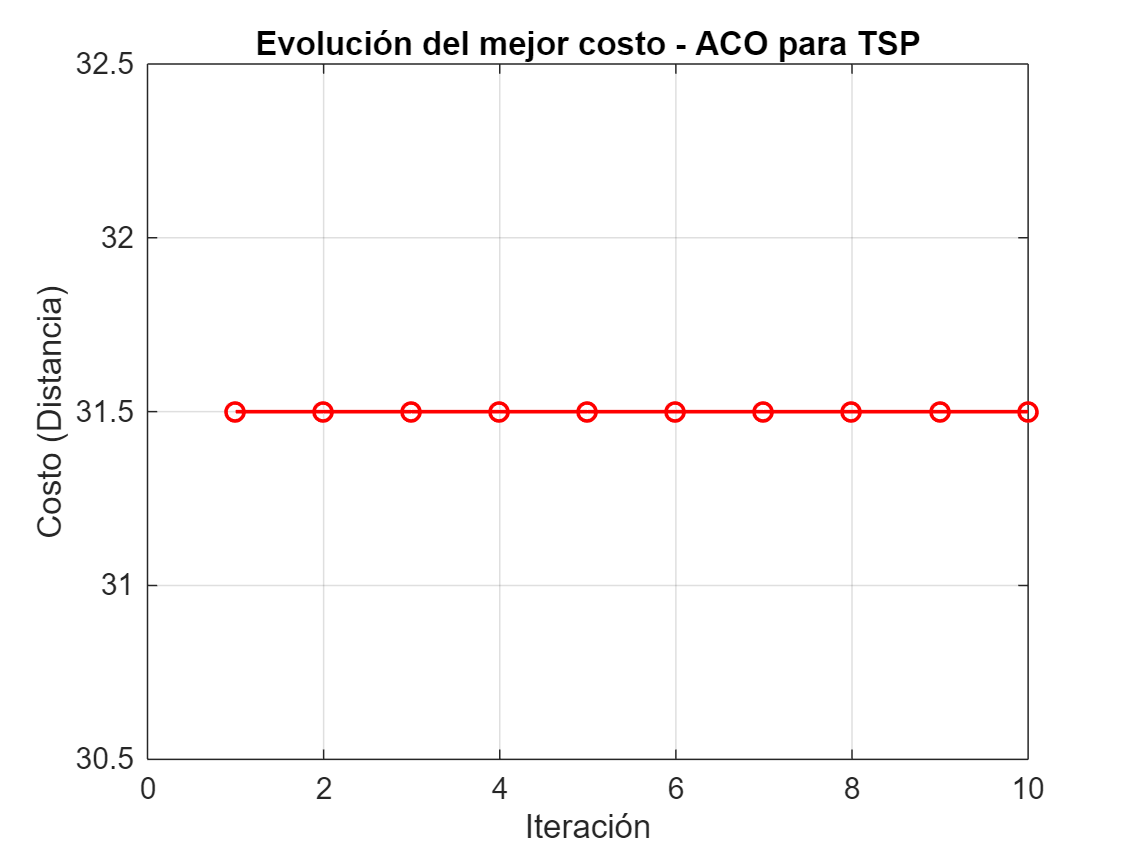


% Graficamos la evolución del mejor costo por iteración:
figure;
plot(1:maxIteraciones, costoIter, 'r-o','LineWidth',1.2);
xlabel('Iteración'); ylabel('Costo (Distancia)'); grid on;
title('Evolución del mejor costo - ACO para TSP');

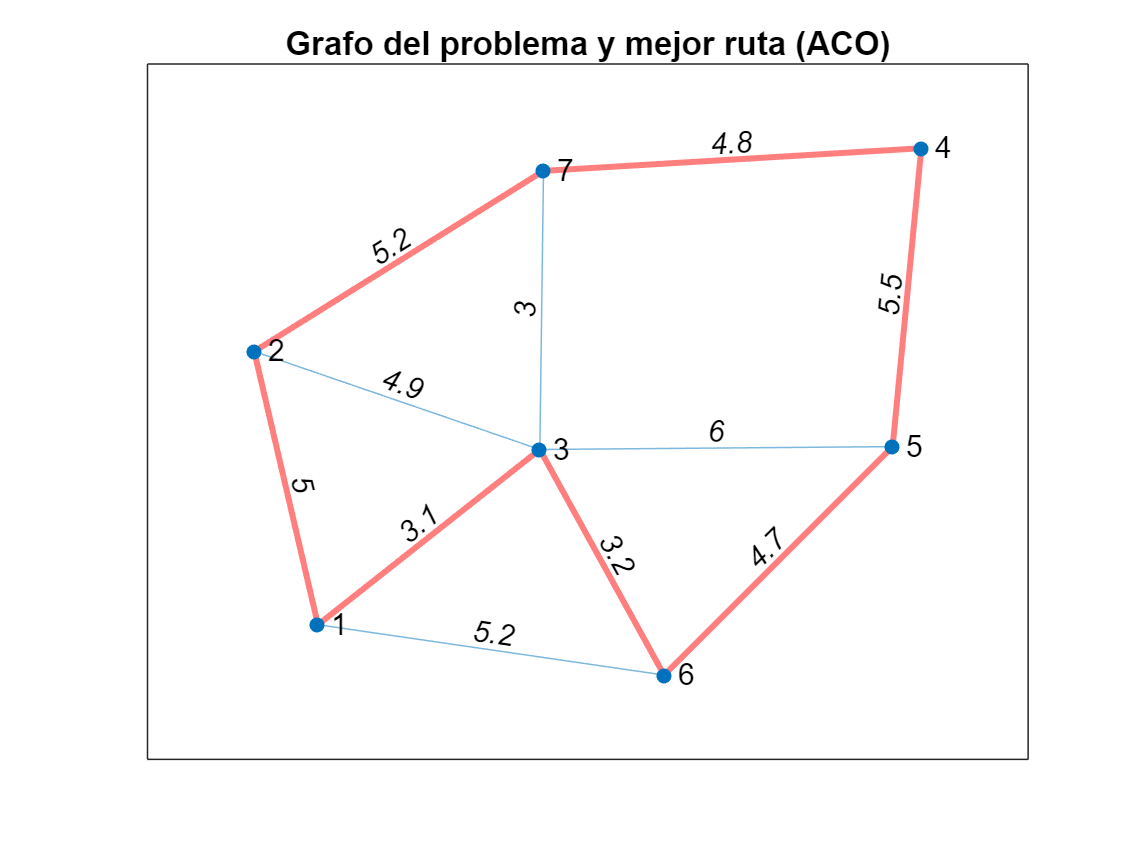


%% GRAFO Y MEJOR RUTA
% Construimos el grafo a partir de nodos1, nodos2, peso
G = graph(nodos1, nodos2, peso);

figure; 
p = plot(G,'EdgeLabel',G.Edges.Weight);
title('Grafo del problema y mejor ruta (ACO)');
hold on;

% Resaltamos la mejor ruta en color rojo (si existe)
for i = 1:numNodos
    highlight(p, mejorRecorrido(i), mejorRecorrido(i+1), ...
        'EdgeColor','r','LineWidth',2);
end
hold off;